# 2D Kalman Filter

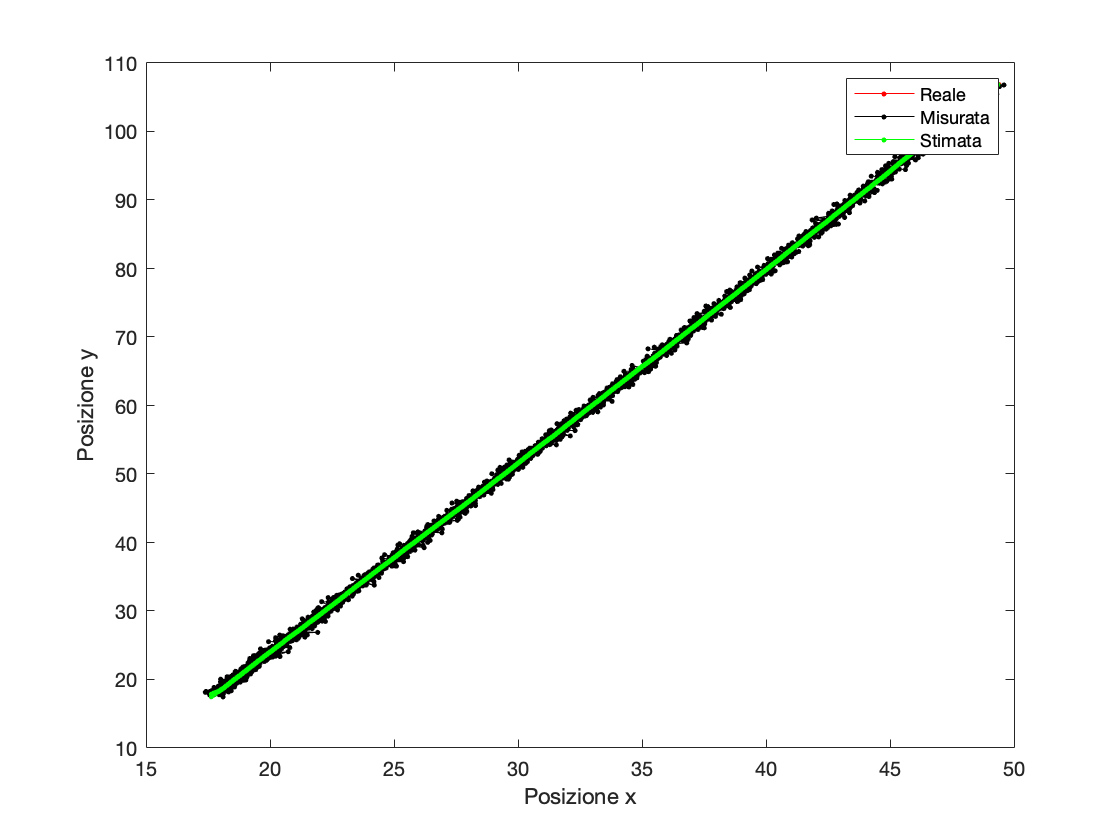

clear all; %Pulisce il workspace
load('Dati_simulazione.mat'); %Carica i dati del INS

n = length(INS_1); %Numero di campioni della traiettoria

%Condizioni iniziali
init.px = INS_1(1).ActorPoses(1).Position(1); %Posizione
init.py = INS_1(1).ActorPoses(1).Position(2);

init.vx = INS_1(1).ActorPoses(1).Velocity(1);
init.vy = INS_1(1).ActorPoses(1).Velocity(2);

%Tempo
t0 = 0; %Istante iniziale
tf = INS_1(n).Time;
deltat = round(((tf-t0)/n), 2); %"Passo di simulazione"
t = linspace(t0, tf, n);

%Dati macchina simulati
esatti = [INS_1.ActorPoses];
esatti = esatti(1, :);

%Dati sensore INS macchina simulata
misurati = cell2mat([INS_1.INSMeasurements]);


% Kalman filter

A = [1 0 deltat 0;
     0 1 0 deltat;
     0 0 1 0;
     0 0 0 1]; % Matrice transizione di stato

B = [0.5*deltat^2 0;
     0 0.5*deltat^2;
     deltat 0 ;
     0 deltat]; % Matrice degli input

H = eye(length(A)); % Matrice di misura

%Init x0
p_est = cell2mat(struct2cell(init));

%Matrice di covarianza P, covarianza del processo Q ed errore di misura R
acc_noise_mag = 0.05;
sensor_noise_mag = 0.2;
R = sensor_noise_mag^2; %R, errore di misura, matrice di covarianza di misura
Q = acc_noise_mag^2 * B * B'; %Rumore del processo

kalman(1).P = eye(4); % Stima della varianza nella posizione iniziale


stimata.x = [];
stimata.y = [];
stimata.vx = [];
stimata.vy = [];

ideale.x = [];
ideale.y = [];
ideale.vx = [];
ideale.vy = [];

misurata.x = [];
misurata.y = [];
misurata.vx = [];
misurata.vy = [];

%Init
stimata.x = p_est(1);
stimata.y = p_est(2);
stimata.vx = p_est(3);
stimata.vy = p_est(4);


ideale.x = p_est(1);
ideale.y = p_est(2);
ideale.vx = p_est(3);
ideale.vy = p_est(4);

misurata.x = p_est(1);
misurata.y = p_est(2);
misurata.vx = p_est(3);
misurata.vy = p_est(4);


for i = 1:n-1
    u = [misurati(i).Acceleration(1); misurati(i).Acceleration(2)];
    Y = [misurati(i).Position(1)-1.5; misurati(i).Position(2); misurati(i).Velocity(1); misurati(i).Velocity(2)];
    p_est = A * p_est + B * u;
    kalman(i+1).P = A * kalman(i).P * A' + Q;
    kalman(i).K = kalman(i+1).P*H'*inv(H*kalman(i+1).P*H'+R*eye(length(A)));
    p_est = p_est + kalman(i).K * (Y - H*p_est);
    kalman(i+1).P = ( eye(length(A)) - kalman(i).K*H ) * kalman(i+1).P; %Eye -> genera una matrice identità
    
    stimata.x = [stimata.x; p_est(1)];
    stimata.y = [stimata.y; p_est(2)];
    stimata.vx = [stimata.vx; p_est(3)];
    stimata.vy = [stimata.vy; p_est(4)];
    
    misurata.x = [misurata.x; Y(1)];
    misurata.y = [misurata.y; Y(2)];
    misurata.vx = [misurata.vx; Y(3)];
    misurata.vy = [misurata.vy; Y(4)];
    
    ideale.x = [ideale.x; esatti(i).Position(1)];
    ideale.y = [ideale.y; esatti(i).Position(2)];
    ideale.vx = [ideale.vx; esatti(i).Velocity(1)];
    ideale.vy = [ideale.vy; esatti(i).Velocity(2)];
end
% Grafico
%plot(stimata.x, stimata.y)
plot(ideale.x,ideale.y,'r.-',misurata.x,misurata.y,'k.-', stimata.x, stimata.y,'g.-');
legend('Reale','Misurata','Stimata');
xlabel("Posizione x");
ylabel("Posizione y");

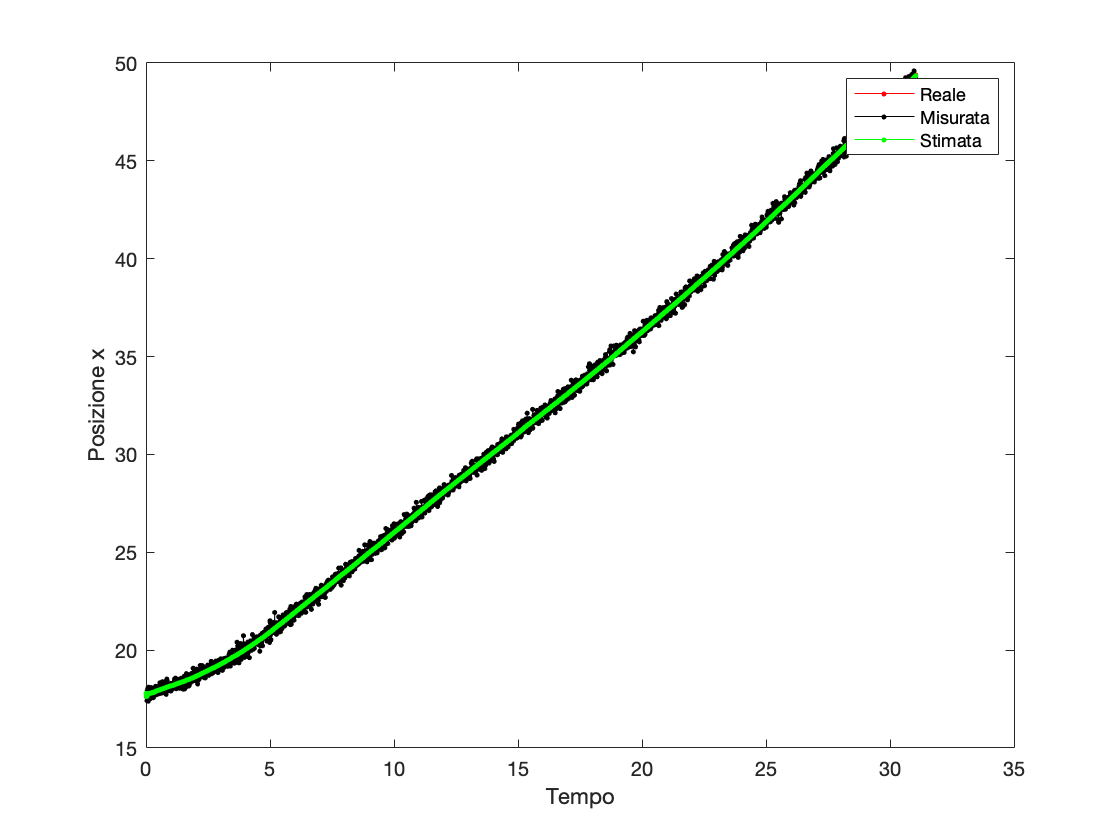

plot(t,ideale.x,'r.-',t,misurata.x,'k.-', t,stimata.x,'g.-');
legend('Reale','Misurata','Stimata');
xlabel("Tempo");
ylabel("Posizione x");

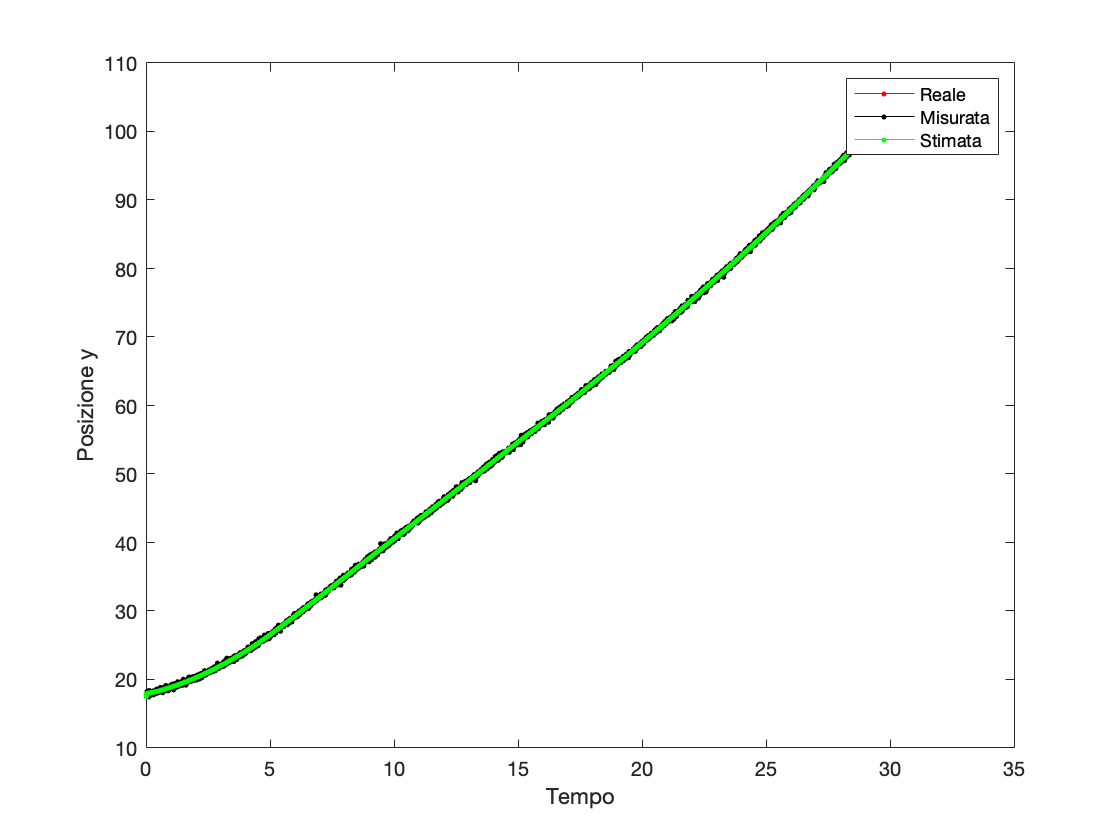

plot(t,ideale.y,'r.-',t,misurata.y,'k.-', t,stimata.y,'g.-');
legend('Reale','Misurata','Stimata');
xlabel("Tempo");
ylabel("Posizione y");

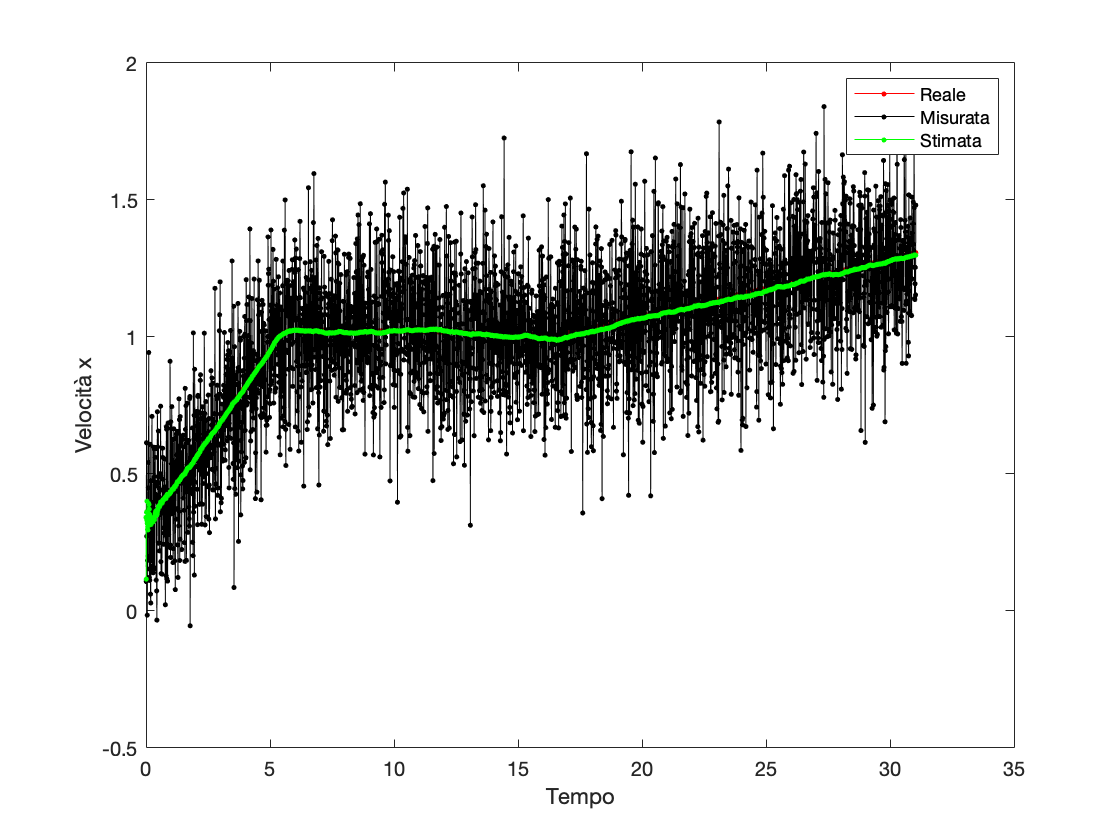

%Velocità X
plot(t,ideale.vx,'r.-',t,misurata.vx,'k.-', t,stimata.vx,'g.-');
legend('Reale','Misurata','Stimata');
xlabel("Tempo");
ylabel("Velocità x");

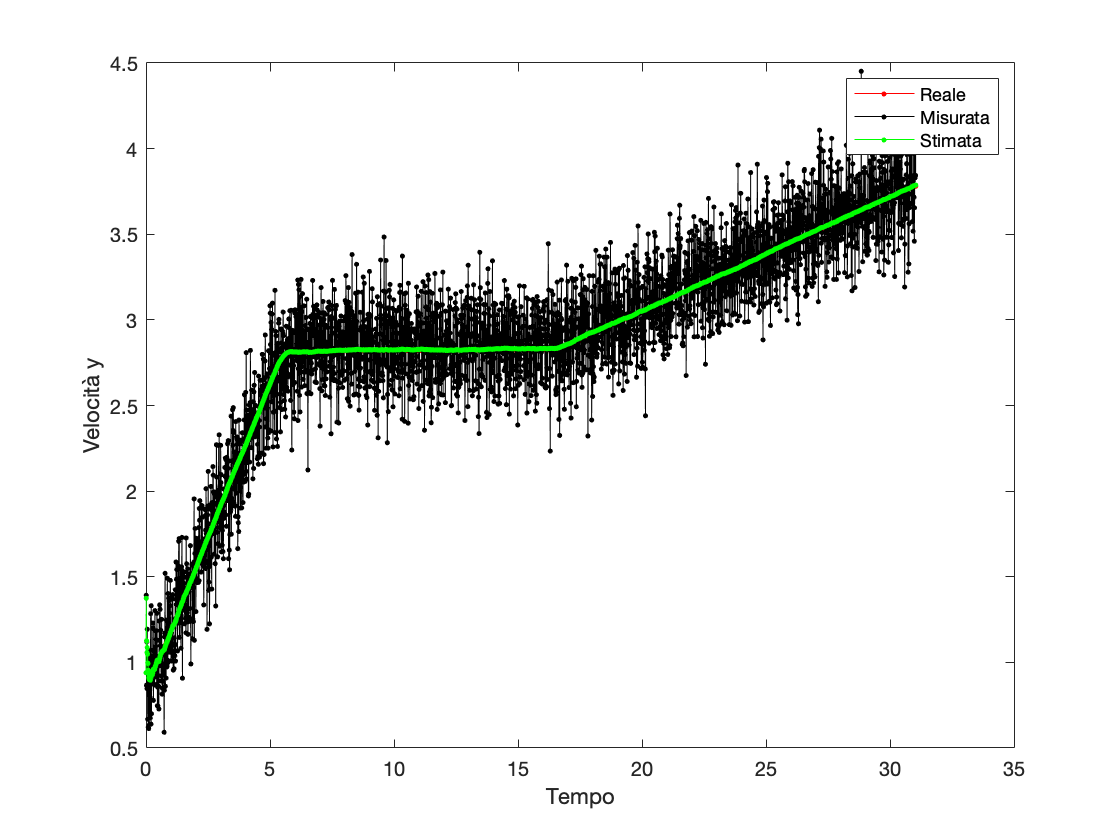

%Velocità Y
plot(t,ideale.vy,'r.-',t,misurata.vy,'k.-', t,stimata.vy,'g.-');
legend('Reale','Misurata','Stimata');
xlabel("Tempo");
ylabel("Velocità y");